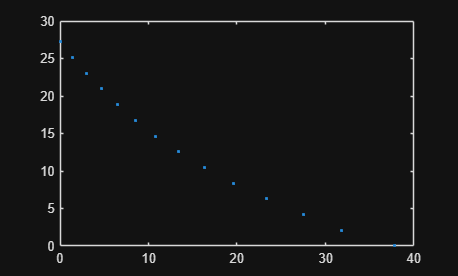

fft_data = load("proj_resources/fidget_spinner.mat");
    
freq_list = fft_data.freq_list / 3; % divide by 3 to get real data
t_list = fft_data.t_list;

plot(t_list, freq_list, ".");


angular_acceleration = diff(freq_list) ./ diff(t_list)

angular_acceleration =    -1.4784   -1.3368   -1.2504   -1.1424   -1.0429   -0.9274   -0.8081   -0.7100   -0.6283   -0.5610   -0.5057   -0.4918   -0.3505


plot(freq_list, [angular_acceleration(1), angular_acceleration], "."); hold on
[coeffs, b, c] = polyfit(freq_list, [angular_acceleration(1), angular_acceleration], 2)

coeffs =    -0.0315   -0.3816   -0.8787


b = struct with fields:
           R: [3×3 double]
          df: 11
       normr: 0.1271
    rsquared: 0.9916


c =    13.6136
    8.7615


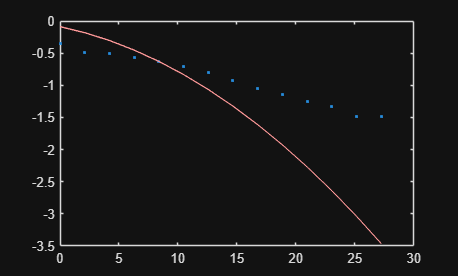

a = coeffs(1); b = coeffs(2); c = coeffs(3);
gov_eq = @(x) (a .* x.^2 + b .* x + c) / 10;
plot(freq_list, gov_eq(freq_list), Color=[1, 0.6, 0.6]);